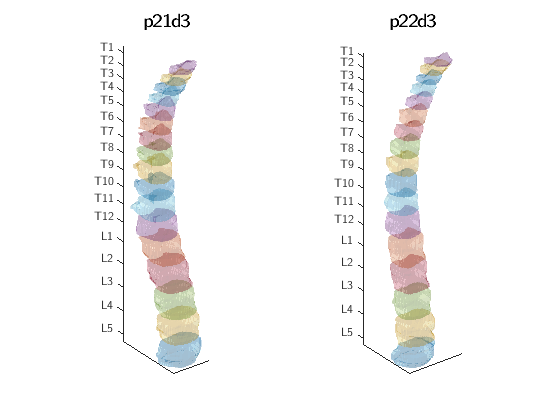

set(0,'DefaultTextFontname', 'LM Sans 12')
set(0,'DefaultAxesFontName', 'LM Sans 12')

figure()
subplot(1,2,1);
[verts, vert_idxs] = createVertStruct([21 3]);
zs = zeros(512);
vert3d = cat(3, zs, verts(1).mask_data, zs, ...
                    verts(2).mask_data, zs, ...
                    verts(3).mask_data, zs, ...
                    verts(4).mask_data, zs, ...
                    verts(5).mask_data, zs, ...
                    verts(6).mask_data, zs, ...
                    verts(7).mask_data, zs, ...
                    verts(8).mask_data, zs, ...
                    verts(9).mask_data, zs, ...
                    verts(10).mask_data, zs, ...
                    verts(11).mask_data, zs, ...
                    verts(12).mask_data, zs, ...
                    verts(13).mask_data, zs, ...
                    verts(14).mask_data, zs, ...
                    verts(15).mask_data, zs, ...
                    verts(16).mask_data, zs, ...
                    verts(17).mask_data, zs);
fv = isosurface(vert3d, .9);
colors = zeros(length(fv.vertices),1);
nvi = vert_idxs - min(vert_idxs);
for idx = 1:length(colors)
    for vIdx = 1:length(verts)
        if fv.vertices(idx, 3) >= nvi(vIdx)+1 && fv.vertices(idx, 3) < nvi(vIdx+1)+1
            colors(idx) = vIdx;
        end
    end
end
colormap("lines")
p = patch(fv,'FaceVertexCData', colors, 'FaceColor', 'interp', 'CDataMapping', 'scaled', 'EdgeColor','none');
p.FaceAlpha = 0.2;
[zt, zl] = getVertTickLabels(vert_idxs);
zticks(zt);
zticklabels(zl);
xticks([]);
yticks([]);
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-10)
lighting flat
title("\fontsize{14}p21d3")

subplot(1,2,2);
[verts, vert_idxs] = createVertStruct([22 3]);
zs = zeros(512);
vert3d = cat(3, zs, verts(1).mask_data, zs, ...
                    verts(2).mask_data, zs, ...
                    verts(3).mask_data, zs, ...
                    verts(4).mask_data, zs, ...
                    verts(5).mask_data, zs, ...
                    verts(6).mask_data, zs, ...
                    verts(7).mask_data, zs, ...
                    verts(8).mask_data, zs, ...
                    verts(9).mask_data, zs, ...
                    verts(10).mask_data, zs, ...
                    verts(11).mask_data, zs, ...
                    verts(12).mask_data, zs, ...
                    verts(13).mask_data, zs, ...
                    verts(14).mask_data, zs, ...
                    verts(15).mask_data, zs, ...
                    verts(16).mask_data, zs, ...
                    verts(17).mask_data, zs);
fv = isosurface(vert3d, .9);
colors = zeros(length(fv.vertices),1);
nvi = vert_idxs - min(vert_idxs);
for idx = 1:length(colors)
    for vIdx = 1:length(verts)
        if fv.vertices(idx, 3) >= nvi(vIdx)+1 && fv.vertices(idx, 3) < nvi(vIdx+1)+1
            colors(idx) = vIdx;
        end
    end
end
colormap("lines")
p = patch(fv,'FaceVertexCData', colors, 'FaceColor', 'interp', 'CDataMapping', 'scaled', 'EdgeColor','none');
p.FaceAlpha = 0.2;
[zt, zl] = getVertTickLabels(vert_idxs);
zticks(zt);
zticklabels(zl);
xticks([]);
yticks([]);
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-10)
lighting flat
title("\fontsize{14}p22d3")


% subplot(1,4,3);
% [verts, vert_idxs] = createVertStruct([9 3]);
% zs = zeros(512);
% vert3d = cat(3, zs, verts(1).mask_data, zs, ...
%                     verts(2).mask_data, zs, ...
%                     verts(3).mask_data, zs, ...
%                     verts(4).mask_data, zs, ...
%                     verts(5).mask_data, zs, ...
%                     verts(6).mask_data, zs, ...
%                     verts(7).mask_data, zs, ...
%                     verts(8).mask_data, zs, ...
%                     verts(9).mask_data, zs, ...
%                     verts(10).mask_data, zs, ...
%                     verts(11).mask_data, zs, ...
%                     verts(12).mask_data, zs, ...
%                     verts(13).mask_data, zs, ...
%                     verts(14).mask_data, zs, ...
%                     verts(15).mask_data, zs, ...
%                     verts(16).mask_data, zs, ...
%                     verts(17).mask_data, zs);
% fv = isosurface(vert3d, .9);
% colors = zeros(length(fv.vertices),1);
% nvi = vert_idxs - min(vert_idxs);
% for idx = 1:length(colors)
%     for vIdx = 1:length(verts)
%         if fv.vertices(idx, 3) >= nvi(vIdx)+1 && fv.vertices(idx, 3) < nvi(vIdx+1)+1
%             colors(idx) = vIdx;
%         end
%     end
% end
% colormap("lines")
% p = patch(fv,'FaceVertexCData', colors, 'FaceColor', 'interp', 'CDataMapping', 'scaled', 'EdgeColor','none');
% p.FaceAlpha = 0.2;
% [zt, zl] = getVertTickLabels(vert_idxs);
% zticks(zt);
% zticklabels(zl);
% xticks([]);
% yticks([]);
% view(3)
% daspect([1,1,1/3])
% axis tight
% camlight
% camlight(-80,-10)
% lighting flat
% title("\fontsize{14}p9d3")
% subplot(1,4,4);
% [verts, vert_idxs] = createVertStruct([10 3]);
% zs = zeros(512);
% vert3d = cat(3, zs, verts(1).mask_data, zs, ...
%                     verts(2).mask_data, zs, ...
%                     verts(3).mask_data, zs, ...
%                     verts(4).mask_data, zs, ...
%                     verts(5).mask_data, zs, ...
%                     verts(6).mask_data, zs, ...
%                     verts(7).mask_data, zs, ...
%                     verts(8).mask_data, zs, ...
%                     verts(9).mask_data, zs, ...
%                     verts(10).mask_data, zs, ...
%                     verts(11).mask_data, zs, ...
%                     verts(12).mask_data, zs, ...
%                     verts(13).mask_data, zs, ...
%                     verts(14).mask_data, zs, ...
%                     verts(15).mask_data, zs, ...
%                     verts(16).mask_data, zs, ...
%                     verts(17).mask_data, zs);
% fv = isosurface(vert3d, .9);
% colors = zeros(length(fv.vertices),1);
% nvi = vert_idxs - min(vert_idxs);
% for idx = 1:length(colors)
%     for vIdx = 1:length(verts)
%         if fv.vertices(idx, 3) >= nvi(vIdx)+1 && fv.vertices(idx, 3) < nvi(vIdx+1)+1
%             colors(idx) = vIdx;
%         end
%     end
% end
% colormap("lines")
% p = patch(fv,'FaceVertexCData', colors, 'FaceColor', 'interp', 'CDataMapping', 'scaled', 'EdgeColor','none');
% p.FaceAlpha = 0.2;
% [zt, zl] = getVertTickLabels(vert_idxs);
% zticks(zt);
% zticklabels(zl);
% xticks([]);
% yticks([]);
% view(3)
% daspect([1,1,1/3])
% axis tight
% camlight
% camlight(-80,-10)
% lighting flat
% title("\fontsize{14}p10d3")